# Feedback linealization for a magnetic levitation 

# system

clear
clc

Definicion de sistema:

syms x1 x2 x3 x4
syms T1 Mg a1 b1 I B
syms u
% T1=0.3; 
% Mg=0.0383; 
% a1=0.105; 
% b1=9.36e-3; 
% I=4.37e-3;
% B=1.84e-3;


x=[x1; x2; x3 ;x4];
f1 = x2

$$f1 = x_{2}$$

f2 = (1/I)*(-Mg*sin(x1)-B*x2+b1*x3+a1*x3^2)

$$f2 = -\frac{-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)}{\text{I}}$$

f3 = (1/T1)*(-x3+x4)

$$f3 = -\frac{x_{3}-x_{4}}{T_{1}}$$

f4 = (1/T1)*(-x4)

$$f4 = -\frac{x_{4}}{T_{1}}$$

f=[f1; f2; f3; f4];
gs=[0; 0; 0; (1/T1)]

$$gs = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{1}{T_{1}} \end{array}\right)$$

h=x1

$$h = x_{1}$$

DERIVADAS DE LI

Lfh=gradient(h,x).'*f; %% z2
Lf2h=gradient(Lfh,x).'*f; %% z3
Lf3h=gradient(Lf2h,x).'*f; %% z4
Lf4h=gradient(Lf3h,x).'*f %% az

$$Lf4h = \begin{array}{l} x_{2}\,\left(\frac{B\,\mathrm{Mg}\,\cos\left(x_{1}\right)}{{\text{I}}^{2}}+\frac{\mathrm{Mg}\,x_{2}\,\sin\left(x_{1}\right)}{\text{I}}\right)-\frac{\left(\frac{B^{2}}{{\text{I}}^{2}}-\frac{\mathrm{Mg}\,\cos\left(x_{1}\right)}{\text{I}}\right)\,\left(-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)\right)}{\text{I}}+\frac{\left(x_{3}-x_{4}\right)\,\left(\frac{B\,\sigma_{1}}{{\text{I}}^{2}}+\frac{\sigma_{1}}{\text{I}\,T_{1}}+\frac{2\,a_{1}\,\left(x_{3}-x_{4}\right)}{\text{I}\,T_{1}}\right)}{T_{1}}-\frac{x_{4}\,\sigma_{1}}{\text{I}\,{T_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=b_{1}+2\,a_{1}\,x_{3} \end{array}$$

Lg3h=gradient(Lf3h,x).'*gs %% bz

$$Lg3h = \frac{b_{1}+2\,a_{1}\,x_{3}}{\text{I}\,{T_{1}}^{2}}$$




syms z [4 1]
syms V
zz1=x1

$$zz1 = x_{1}$$

zz2=Lfh

$$zz2 = x_{2}$$

zz3=Lf2h

$$zz3 = -\frac{-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)}{\text{I}}$$

zz4=Lf3h

$$zz4 = \frac{B\,\left(-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)\right)}{{\text{I}}^{2}}-\frac{\left(x_{3}-x_{4}\right)\,\left(b_{1}+2\,a_{1}\,x_{3}\right)}{\text{I}\,T_{1}}-\frac{\mathrm{Mg}\,x_{2}\,\cos\left(x_{1}\right)}{\text{I}}$$

Z=[zz1;zz2;zz3;zz4]

$$Z = \left(\begin{array}{c} x_{1}\\ x_{2}\\ -\frac{-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)}{\text{I}}\\ \frac{B\,\left(-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)\right)}{{\text{I}}^{2}}-\frac{\left(x_{3}-x_{4}\right)\,\left(b_{1}+2\,a_{1}\,x_{3}\right)}{\text{I}\,T_{1}}-\frac{\mathrm{Mg}\,x_{2}\,\cos\left(x_{1}\right)}{\text{I}} \end{array}\right)$$

v=Lf4h+Lg3h*u;
v=simplify(v);
Lf4h=simplify(Lf4h,"Steps",100);% alpha


u=(1/Lg3h)*(V-Lf4h)

$$u = \begin{array}{l} \frac{\text{I}\,{T_{1}}^{2}\,\left(V+\frac{\left(B^{2}-\text{I}\,\mathrm{Mg}\,\cos\left(x_{1}\right)\right)\,\left(-a_{1}\,{x_{3}}^{2}-b_{1}\,x_{3}+B\,x_{2}+\mathrm{Mg}\,\sin\left(x_{1}\right)\right)}{{\text{I}}^{3}}+\frac{x_{4}\,\sigma_{1}}{\text{I}\,{T_{1}}^{2}}-\frac{\mathrm{Mg}\,x_{2}\,\left(B\,\cos\left(x_{1}\right)+\text{I}\,x_{2}\,\sin\left(x_{1}\right)\right)}{{\text{I}}^{2}}-\frac{\left(x_{3}-x_{4}\right)\,\left(\text{I}\,b_{1}+B\,T_{1}\,b_{1}+4\,\text{I}\,a_{1}\,x_{3}-2\,\text{I}\,a_{1}\,x_{4}+2\,B\,T_{1}\,a_{1}\,x_{3}\right)}{{\text{I}}^{2}\,{T_{1}}^{2}}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b_{1}+2\,a_{1}\,x_{3} \end{array}$$

## Diseño de control 

A = [[zeros(3,1),eye(3)];zeros(1,4)];
B = [zeros(3,1);1];
C = [1, zeros(1,3)];

Aumento de integradores

A = [A zeros(4,1);-C 0];
B = [B;0];

### Diseño de control Lineal

Se diseña el control por realimentación de estados con $v=-K_az_a$ y ganancias de realimentación $K_a$ calculadas con asignación de polos

% Asignación de polos
% aproximación a sistema de 2do orden
ts = 0.8;
zeta = 0.9;
w = 4/(ts*zeta);

p = [1 2*zeta*w w^2];
p = [roots(p)' -5 -10 -15];
K = acker(A,B,p);
k1=K(1);
k2=K(2);
k3=K(3);
k4=K(4);
k5=K(5);
reff=pi/2;
Uss=(-b1+sqrt(b1^2 + 4*a1*Mg*sin(reff)))/(2*a1)

$$Uss = -\frac{b_{1}-\sqrt{{b_{1}}^{2}+4\,\mathrm{Mg}\,a_{1}}}{2\,a_{1}}$$


X1ss=reff

X1ss = 1.5708

X2ss=0

X2ss = 0

X3ss=Uss

$$X3ss = -\frac{b_{1}-\sqrt{{b_{1}}^{2}+4\,\mathrm{Mg}\,a_{1}}}{2\,a_{1}}$$

X4ss=Uss

$$X4ss = -\frac{b_{1}-\sqrt{{b_{1}}^{2}+4\,\mathrm{Mg}\,a_{1}}}{2\,a_{1}}$$

tx1=out.ScopeDataX1.time;
x1_grafica=out.ScopeDataX1.signals(1).values;
ref_grafica=out.ScopeDataX1.signals(2).values;

tx2=out.ScopeDataX2.time;
x2_grafica=out.ScopeDataX2.signals.values;

tx3=out.ScopeDataX3.time;
x3_grafica=out.ScopeDataX3.signals.values;

tx4=out.ScopeDataX4.time;
x4_grafica=out.ScopeDataX4.signals.values;

tU=out.ScopeDataU.time;
U_grafica=out.ScopeDataU.signals.values;

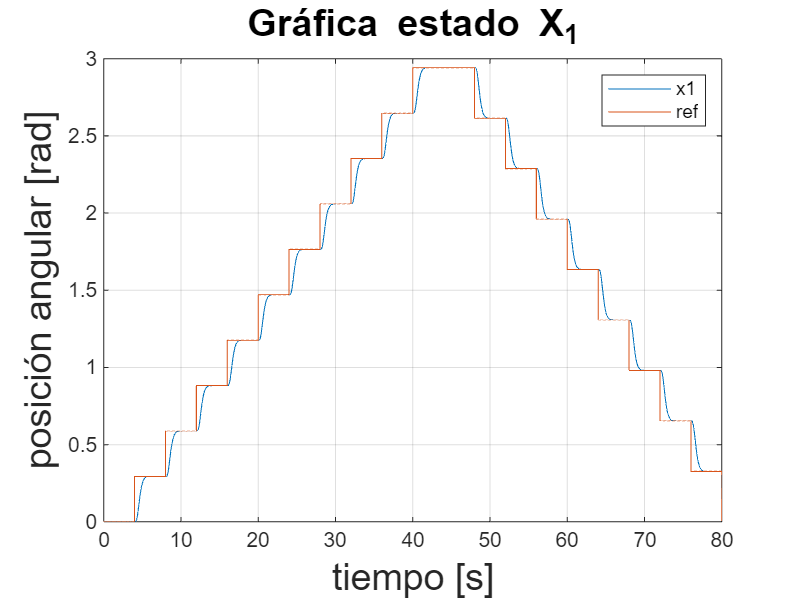

plot(tx1,x1_grafica);
xlabel('tiempo [s]','fontsize',18);
ylabel('posición angular [rad]','fontsize',18);
title('Gráfica estado X_1','fontsize',18);
grid on;
hold on;
plot(tx1,ref_grafica);
legend('x1','ref');
hold off;

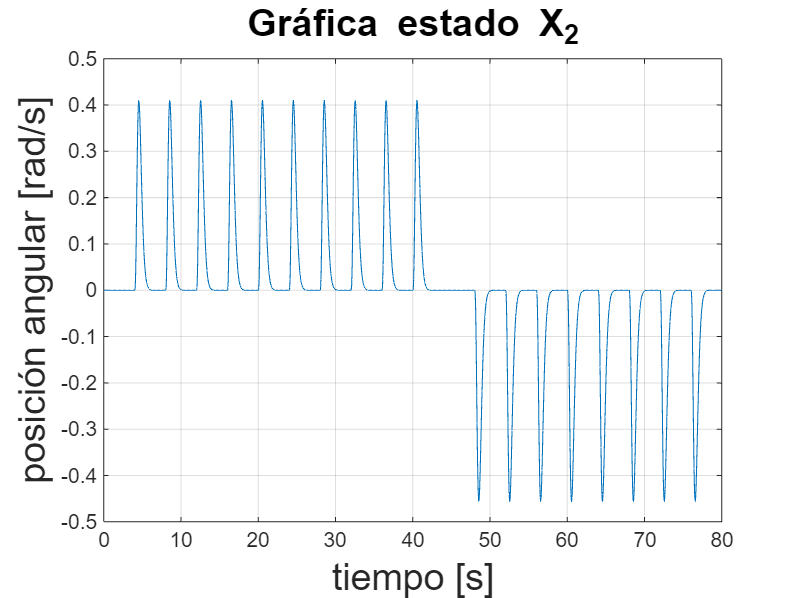


plot(tx2,x2_grafica);
xlabel('tiempo [s]','fontsize',18);
ylabel('posición angular [rad/s]','fontsize',18);
title('Gráfica estado X_2','fontsize',18);
grid on;

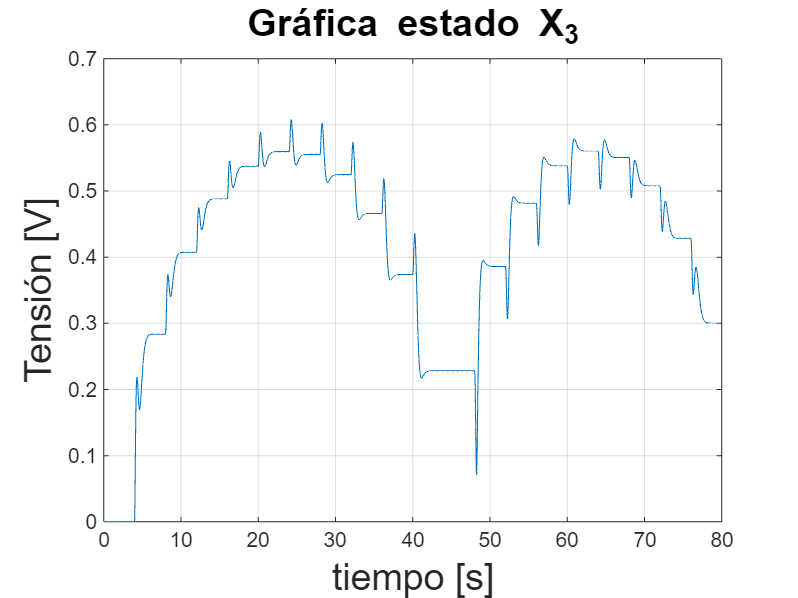


plot(tx3,x3_grafica);
xlabel('tiempo [s]','fontsize',18);
ylabel('Tensión [V]','fontsize',18);
title('Gráfica estado X_3','fontsize',18);
grid on;

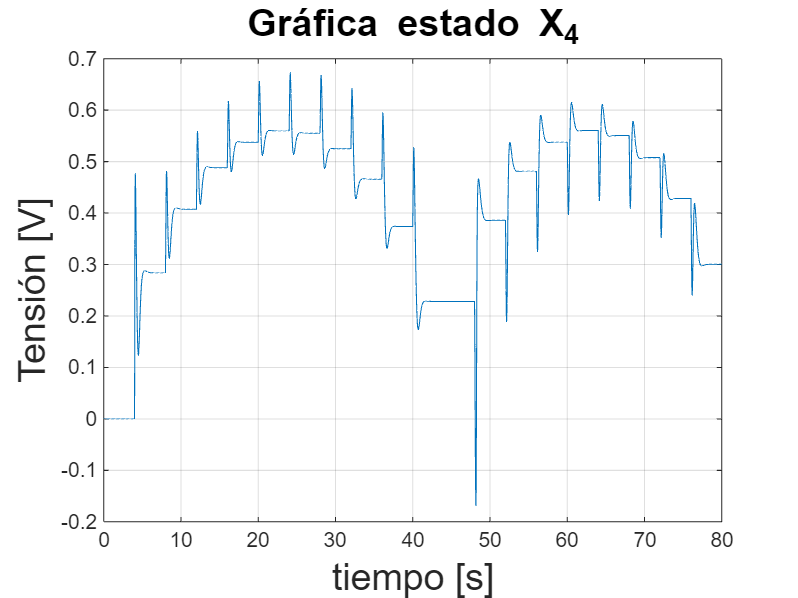


plot(tx4,x4_grafica);
xlabel('tiempo [s]','fontsize',18);
ylabel('Tensión [V]','fontsize',18);
title('Gráfica estado X_4','fontsize',18);
grid on;

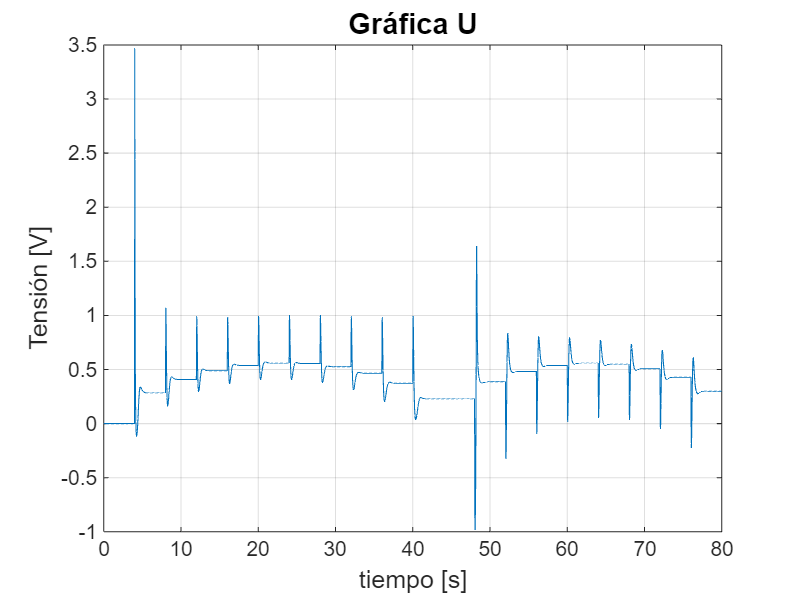


plot(tU,U_grafica);
xlabel('tiempo [s]','fontsize',12);
ylabel('Tensión [V]','fontsize',12);
title('Gráfica U','fontsize',14);
grid on;


%====== FUNCIÓN ESCALERA ============
intervalos=linspace(0,(pi-0.2),11)

intervalos =          0    0.2942    0.5883    0.8825    1.1766    1.4708    1.7650    2.0591    2.3533    2.6474    2.9416


intervalos2=linspace((pi-0.2),0,10)

intervalos2 =     2.9416    2.6147    2.2879    1.9611    1.6342    1.3074    0.9805    0.6537    0.3268         0



inter=[intervalos intervalos2]

inter =          0    0.2942    0.5883    0.8825    1.1766    1.4708    1.7650    2.0591    2.3533    2.6474    2.9416    2.9416    2.6147    2.2879    1.9611    1.6342    1.3074    0.9805    0.6537    0.3268         0
